global fluid mass_flow_rate
fluid = 'air.mix';
mass_flow_rate = 0.45;
[thrust_stat, q_dot_tot, h_jump_usable, efficiency] = turbo_jet(273, 101, 1000, 4);

W_dot_real = 5.9999e+04





T_hot = linspace(700, 1200, 50);
P_ratio = linspace(2, 5, 4);
clear data;

for i=1:length(P_ratio)
    for j=1:length(T_hot)
        [thrust_stat, q_dot_tot, h_jump_usable, efficiency] = turbo_jet(273, 101, T_hot(j), P_ratio(i));
        data(i, j) = efficiency;
    end
end


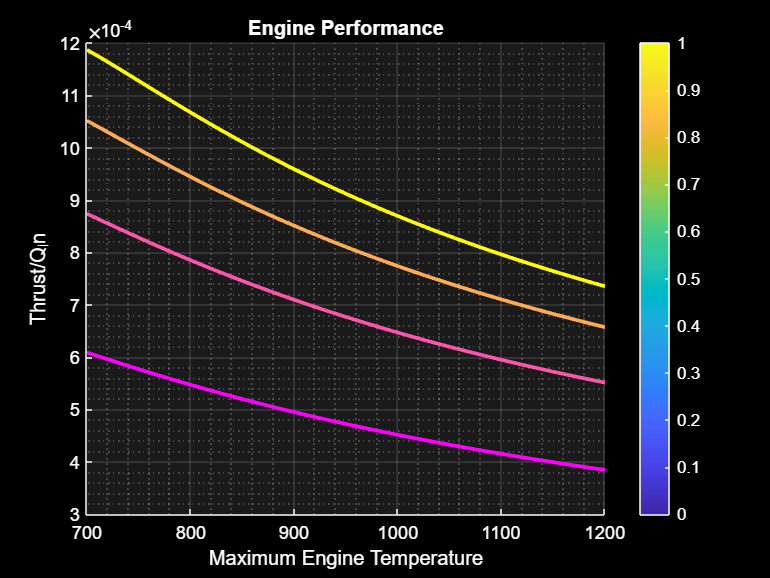

figure(1)
clf
hold on
cmap = spring(length(P_ratio));

for i=1:length(P_ratio)
    plot(T_hot, data(i,:), "LineWidth", 2, "Color", cmap(i,:))
end

 set(gca,'Color', [0.1 0.1 0.1])
    set(gca,'XColor',[1 1 1])
    set(gca,'YColor',[1 1 1])
    set(gca,'ZColor',[1 1 1])
    set(gca,'YColor',[1 1 1])
    set(gcf,'Color','k')
    set(gcf, 'InvertHardcopy', 'off');
print(gcf,'plot.png','-dpng','-r600')

c = colorbar;
c.Color = [1 1 1];
c.
grid on
grid minor
title("Engine Performance", "color", [1 1 1])
ylabel("Thrust/Q_in")
xlabel("Maximum Engine Temperature")



n_united = thrust_stat / q_dot_tot %efficiency in N/W

n_united = 7.3518e-04

n_unitless = mass_flow_rate * h_jump_usable/q_dot_tot %unitless efficiency

n_unitless = 1.0497